# Airfoil Noise Prediction Using ANN

clear
clc

#### Loading dataset

airfoil_self_noise = readtable("airfoil_self_noise.dat");

The dataset contains 1503 data samples. Each sample includes values of "frequency", "angle_of_attack", "chord_length", "fs_velocity", "disp_thickness" and "sound_pressure".

head(airfoil_self_noise)

    Var1    Var2     Var3     Var4      Var5        Var6 
    ____    ____    ______    ____    _________    ______

     800     0      0.3048    71.3    0.0026634     126.2
    1000     0      0.3048    71.3    0.0026634     125.2
    1250     0      0.3048    71.3    0.0026634    125.95
    1600     0      0.3048    71.3    0.0026634    127.59
    2000     0      0.3048    71.3    0.0026634    127.46
    2500     0      0.3048    71.3    0.0026634    125.57
    3150     0      0.3048    71.3    0.0026634     125.2
    4000     0      0.3048    71.3    0.0026634    123.06



This LiveScript is to build and train an ANN that predicts the "sound_pressure" given "frequency", "angle_of_attack", "chord_length", "fs_velocity" and "disp_thickness".

#### Rearanging the dataset

% Spliting the dataset
[trainInd, ~, testInd] = dividerand(size(airfoil_self_noise,1), 0.8, 0, 0.2);
tblTrain = airfoil_self_noise(trainInd,:);  % Extracting training sample inputs
tblTest = airfoil_self_noise(testInd,:); % Extracting testing sample inputs

#### Constructing a neural network

layers = [
    featureInputLayer(size(tblTrain,2)-1) % input layer: # dim, training data
    fullyConnectedLayer(20)             % hidden layer: an initial try
    reluLayer            % ReLU activation func. (not a new layer of neurons)
    fullyConnectedLayer(1) % Output layer: # output dim.
    regressionLayer("Name","output")];

#### Configuring the training options

options = trainingOptions('adam', ...   % using adam optimizer
    'MaxEpochs',4000, ...               % number of epochs of training
    'MiniBatchSize', size(tblTrain, 1), ... % batch training
    'Shuffle','every-epoch', ...        % shuffling the training samples
    'Plots','training-progress', ...    % visualizing the training process
    'ExecutionEnvironment', 'cpu', ...  % training on CPU
    'Verbose',false); % hide notices while training

#### Training the neural network

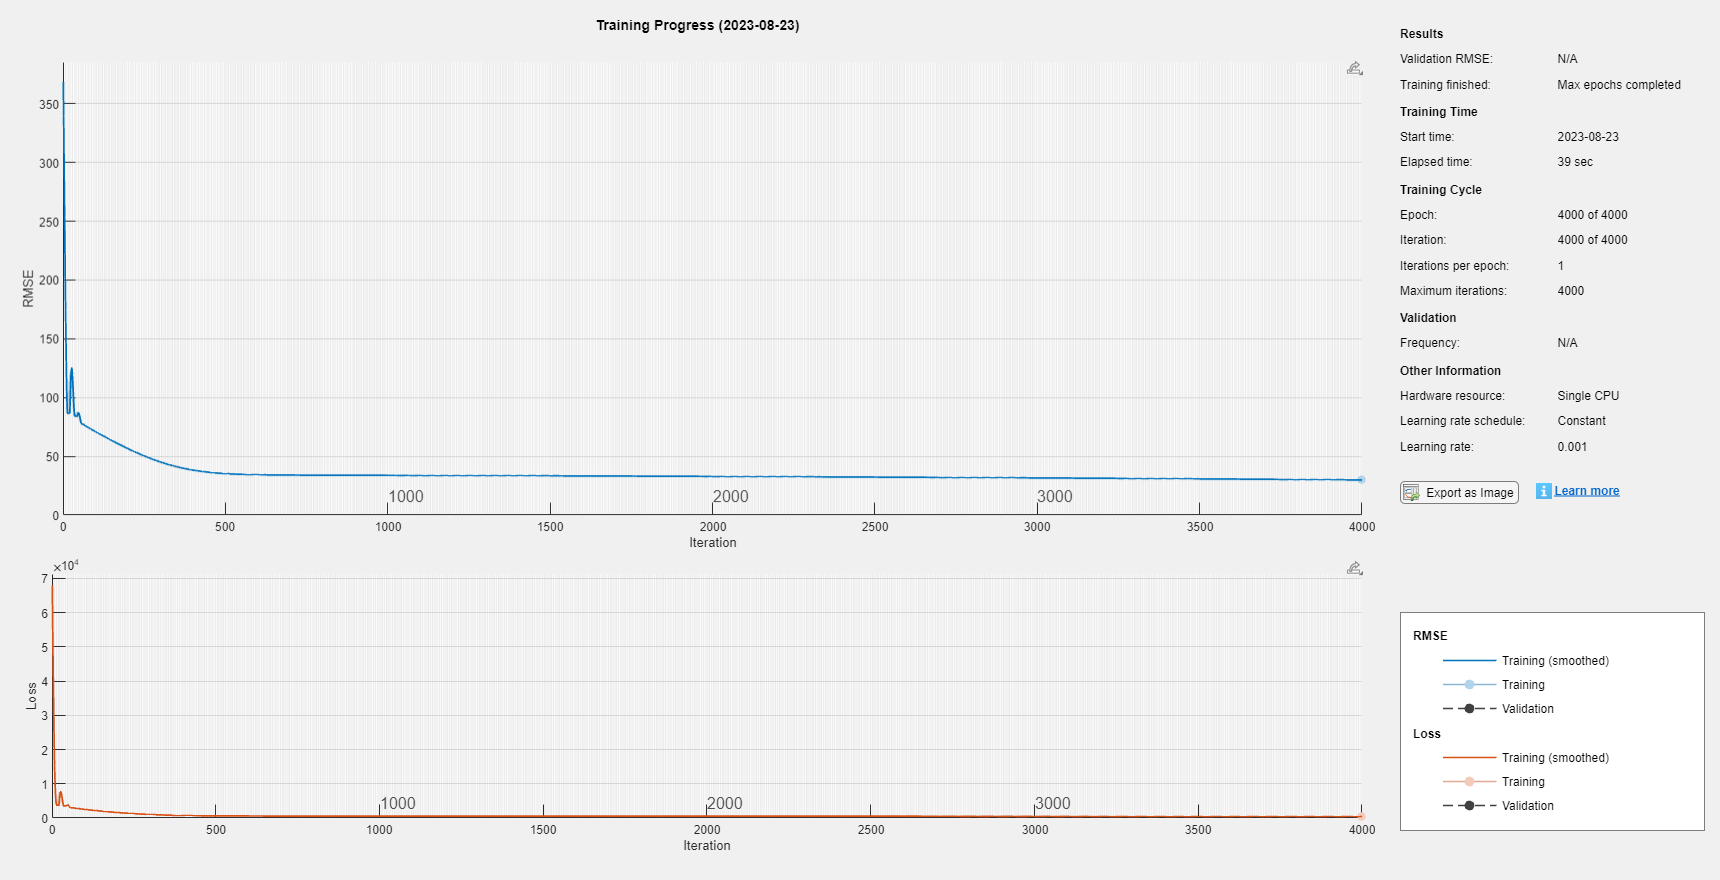

net = trainNetwork(tblTrain, layers, options);

% Predicting y in the test set 
y_pred = predict(net,tblTest);
% Calculating the root-mean-squred-error
rmse = sqrt(sum((y_pred - tblTest.Var6).^2, 'all')/length(tblTest.Var6))

rmse = single
30.2158

#### Constructing a proper network with normalization

layers = [
    featureInputLayer(size(tblTrain, 2)-1, "Normalization","rescale-zero-one")
    fullyConnectedLayer(20)                 % hidden layer: an initial try
    reluLayer             % ReLU activation func. (not a new layer of neurons)
    fullyConnectedLayer(1)   % Output layer: # output dim.
    regressionLayer("Name","output")];

% Configuring the training options
options = trainingOptions('adam', ...   % using adam optimizer
    'MaxEpochs',5000, ...               % more epochs of training
    'MiniBatchSize', size(tblTrain, 1), ... % batch training
    'Shuffle','every-epoch', ...        % shuffling the training samples
    'Plots','training-progress', ...    % visualizing the training process
    'ExecutionEnvironment', 'cpu', ...  % training on CPU
    'Verbose',false); % hide notices while training

#### Training the neural network

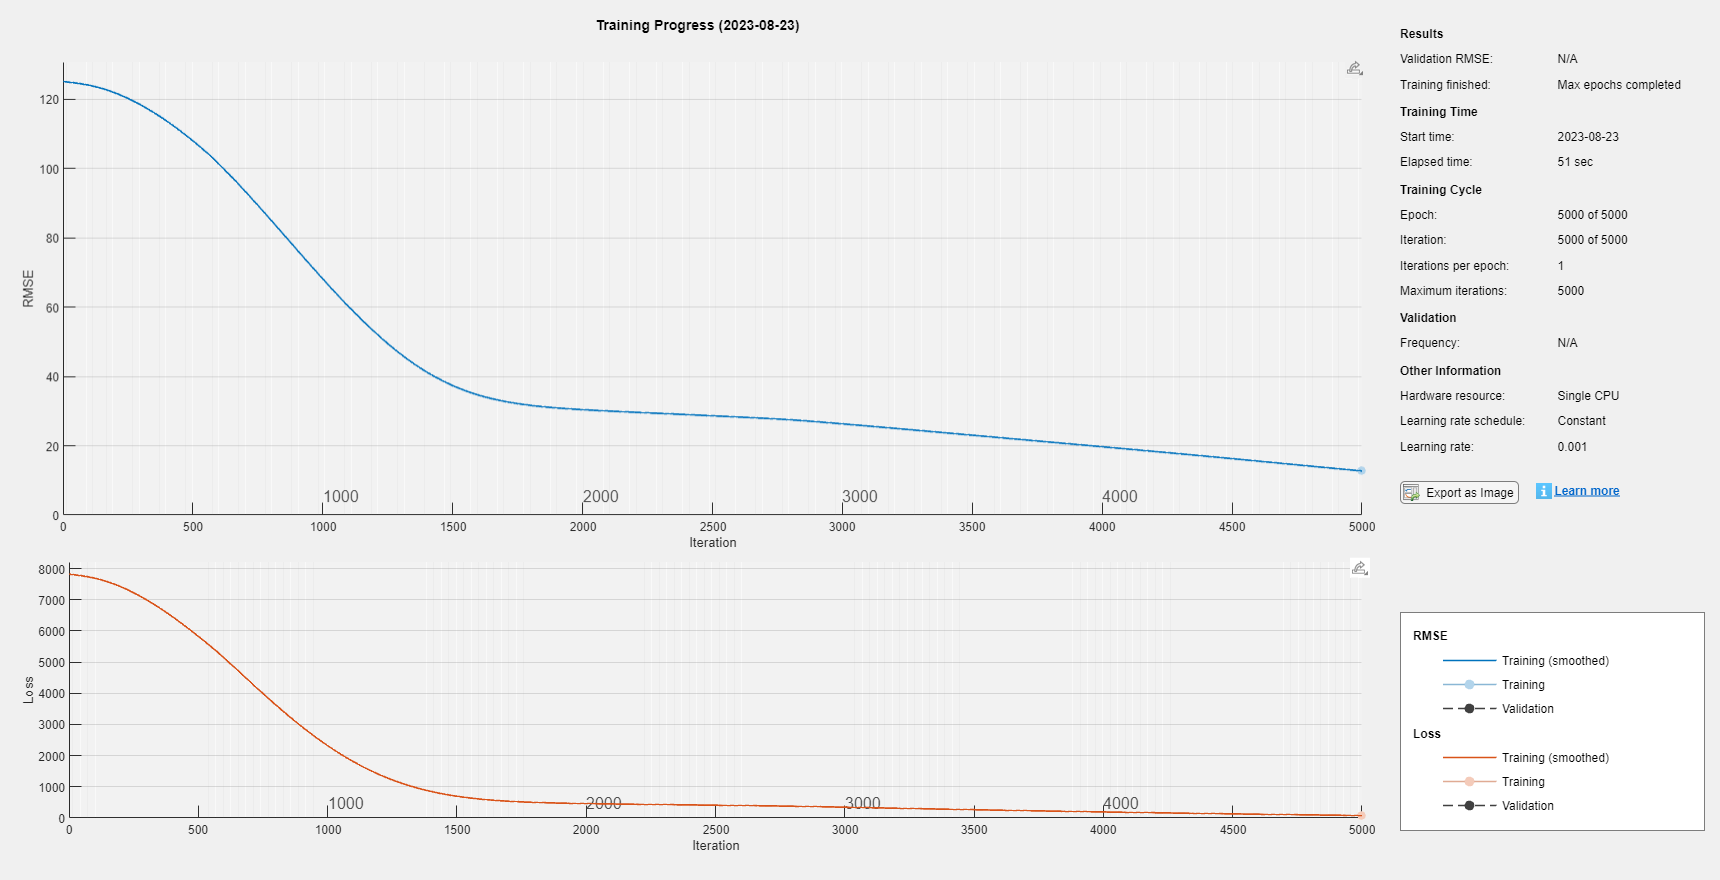

net = trainNetwork(tblTrain, layers, options);

% Predicting y in the test set 
y_pred = predict(net,tblTest);
% Calculating the root-mean-squred-error
rmse = sqrt(sum((y_pred - tblTest.Var6).^2, 'all')/length(tblTest.Var6))

rmse = single
12.8397

#### Constructing a deeper and wider network

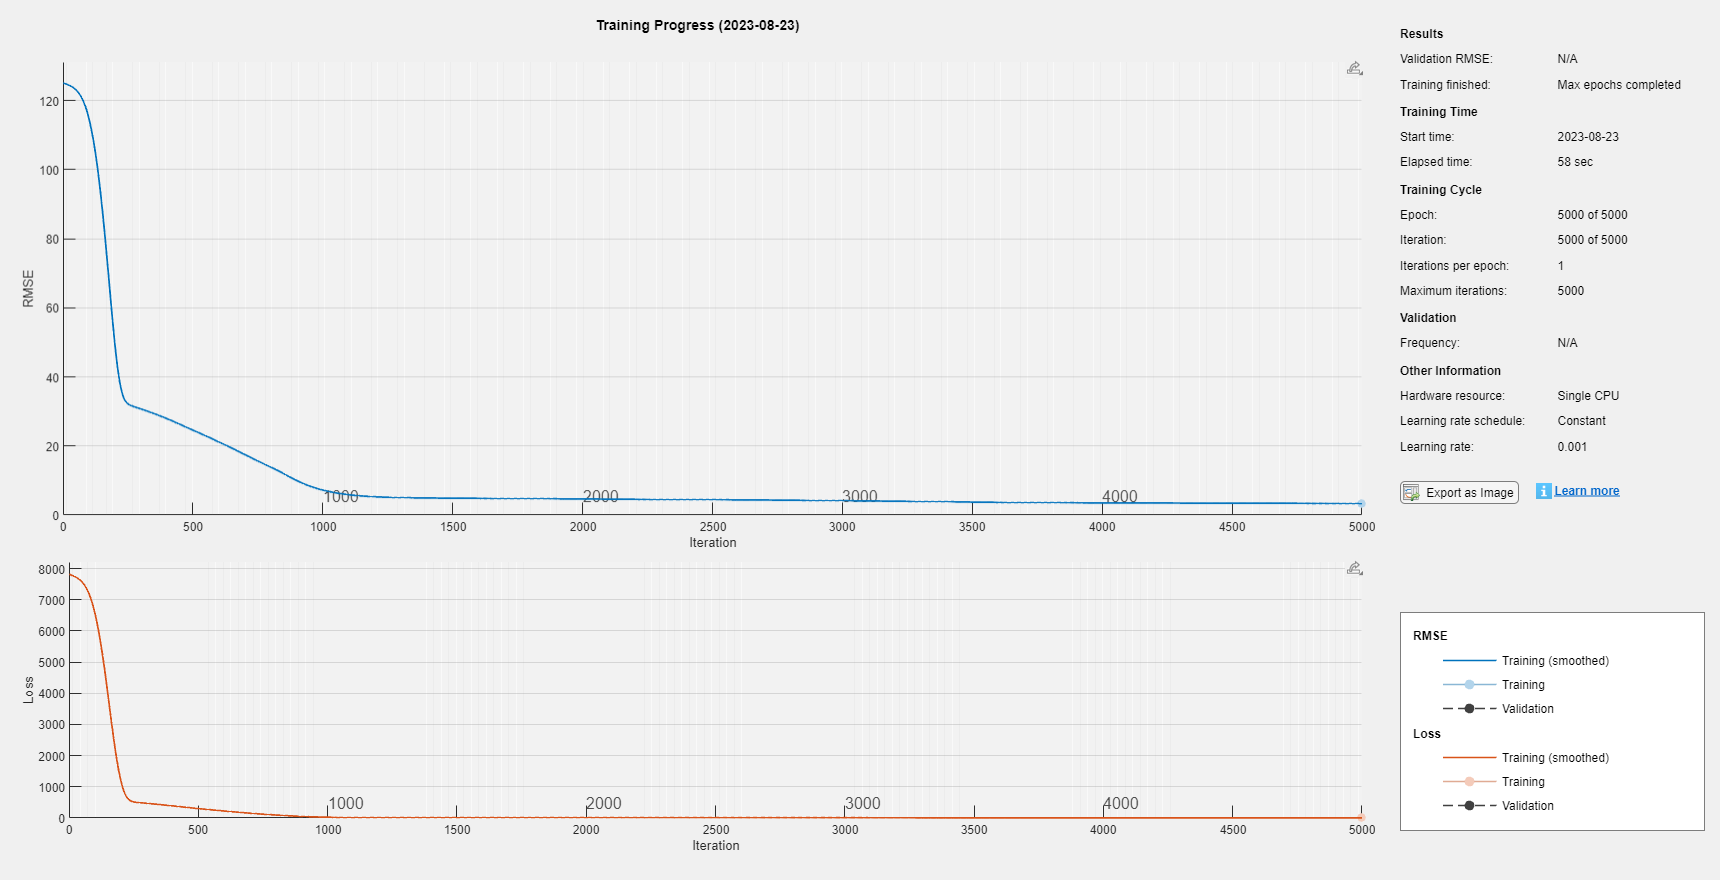

layers = [
    featureInputLayer(size(tblTrain,2)-1,"Normalization","rescale-zero-one")
    fullyConnectedLayer(40) % more neurons in hidden layer
    reluLayer               % ReLU activation func. (not a new layer of neurons)
    fullyConnectedLayer(40) % more neurons in hidden layer
    reluLayer               % ReLU activation func. (not a new layer of neurons)
    fullyConnectedLayer(1)   % Output layer: # output dim.
    regressionLayer("Name","output")];
% Configuring the training options
options = trainingOptions('adam', ...
    'MaxEpochs',5000, ...      % more epochs of training
    'MiniBatchSize', size(tblTrain, 1), ... % batch training
    'Shuffle','every-epoch', ...        % shuffling the training samples
    'Plots','training-progress', ...    % visualizing the training process
    'ExecutionEnvironment', 'cpu', ...  % training on CPU
    'Verbose',false); % hide notices while training

% Training the neural network
net = trainNetwork(tblTrain, layers, options);

% Predicting y in the test set 
y_pred = predict(net,tblTest);
% Calculating the root-mean-squred-error
rmse = sqrt(sum((y_pred - tblTest.Var6).^2, 'all')/length(tblTest.Var6))

rmse = single
3.4089